% main_simulation.m
% 完整的主仿真脚本，整合所有模型和控制器
% 运行后生成时域/频域结果，并输出性能指标（与论文表5-9对应）

clear; clc; close all;

## 1. 仿真参数配置

fs = 10000;                 % 采样率 [Hz]
dt = 1/fs;                  % 时间步长 [s]
duration = 10;              % 仿真时长 [s]
n_samples = duration * fs;  % 总采样点数
t = (0:n_samples-1)' * dt;  % 时间向量

% 振动工况（单频测试，可修改）
vib_freq = 100;             % 振动频率 [Hz]
vib_amp = 5.0;              % 振动幅值 [m/s²]

% 控制器参数
L = 128;                      % 降低滤波器阶数（原 32）
mu_min = 1e-6;              % 极小步长，确保稳定
mu_max = 1e-5;             % 最大步长大大降低（原 0.1）
delta = 1e-6;               % 增大正则化参数，避免除零和步长 过大

% 混合控制器参数
alpha_min = 0;
alpha_max = 0; % 0.8
performance_window = 100;   % 性能评估窗口长度

% 神经网络参数
input_dim = 19;             % 特征维度（见表2）
hidden_dims = [12, 8];      % 隐藏层结构
%nn_pretrain = true;         % 是否预训练神经网络（离线）
% 神经网络（加载预训练模型）
load('trained_nn.mat', 'nn');   % 加载已训练的网络
nn_pretrain = false;            % 不再需要预训练

## 2. 初始化物理模型

振动源（生成参考信号和扰动）

vib_source = VibrationSource();
vib_source.frequencies = vib_freq;
vib_source.amplitudes = vib_amp;
vib_source.phases = 0;
vib_source.noise_level = 0.05;    % 5% 噪声

% 结构动力学模型（默认参数，基于曾威 2006）
structure = StructuralDynamics(fs, 5, false);  % 负载5N，无耦合偏移

负载 5.0 N: 目标平均阻尼比 = 0.0250
  各模态阻尼比: [0.0150, 0.0225, 0.0375]



% 压电作动器（默认参数，基于相晖 2006）
actuator = PiezoActuator();

作动器状态已重置


actuator.K = 0.85;
actuator.fn = 3100;
actuator.zeta = 0.023;
actuator.alpha = 0.15;
actuator.beta = 0.035;
actuator.gamma = 0.025;

% 加速度计（默认参数，基于曾威 2006）
sensor = Accelerometer(fs);

加速度计初始化: PCB 352C33
  灵敏度: 98 mV/g
  带宽: 0.5-3000 Hz
  噪声密度: 6.0 μg/√Hz


sensor.sensitivity = 98;
sensor.bandwidth = [0.5, 3000];
sensor.noise_density = 6e-6;

## 3. 次级路径辨识（离线）

fprintf('辨识次级路径...\n');

辨识次级路径...



% s_hat = estimate_secondary_path(structure, actuator, fs);   % 注释掉原辨识
delay = 4;   % 4 个采样点延迟
s_hat = zeros(delay+1, 1);
s_hat(end) = -0.2;   % 正增益，纯延迟

fprintf('次级路径长度: %d\n', length(s_hat));

次级路径长度: 5


## 4. 控制器初始化

FxLMS

fxLMS = struct();
fxLMS.order = L;
w_init = zeros(L, 1);
fxLMS.w = w_init;
fxLMS.mu_min = mu_min;
fxLMS.mu_max = mu_max;
fxLMS.delta = delta;
fxLMS.S_hat = s_hat(:);          % 确保列向量

% 关键修改：缓冲区长度应足够容纳次级路径长度和滤波器阶数
buffer_len = max(L, length(fxLMS.S_hat));
fxLMS.x_buffer = zeros(buffer_len, 1);   % 用于存储历史参考信号
fxLMS.xf_buffer = zeros(L, 1);           % 用于存储滤波参考信号（长度保持 L）

% 神经网络（纯 MATLAB 手写版）
%nn = ResidualNN_Simple(input_dim, hidden_dims);
% 如果预训练，需生成离线数据并训练（这里简化，仅演示结构）
%if nn_pretrain
    %fprintf('离线预训练神经网络（示例）...\n');
    % 生成一些仿真数据（仅示意，实际应使用长时间仿真数据）
    % 此处可调用一个离线训练函数，为简化略去
%end

% 混合控制器
%hybrid = HybridController(alpha_min, alpha_max, performance_window);
%hybrid.verbose = true;   % 打印状态切换信息

%hybrid = HybridController(0, 0.8, 100);
%hybrid.alpha = 0;                     % 固定混合系数
%hybrid.current_state = 'hybrid_stable'; % 避免状态机干扰
%hybrid.verbose = false;

% 混合控制器（仍保留对象，但不再使用其 combine 和 adapt_alpha）
hybrid = HybridController(0, 1, 100);   % alpha_max=1
hybrid.alpha = 0;                       % 固定 α=1
hybrid.current_state = 'hybrid_stable'; % 避免状态机切换
hybrid.verbose = false;                 % 不打印切换信息

## 5. 预分配存储数组

vibration_raw = zeros(n_samples,1);   % 原始振动（扰动）
control_signal = zeros(n_samples,1);   % 总控制电压
error_signal = zeros(n_samples,1);     % 残余振动（误差）
y_linear = zeros(n_samples,1);         % FxLMS输出
y_nn = zeros(n_samples,1);             % 神经网络输出
alpha_history = zeros(n_samples,1);    % 混合系数历史
mu_history = zeros(n_samples,1);       % 步长历史
rms_history = zeros(n_samples,1);      % 滑动RMS

% 用于收集训练数据（每 10 步记录一次）
data_collect = struct();
data_collect.features = [];
data_collect.targets = [];
collect_interval = 10;  % 每 10 步记录一次

## 6. 主仿真循环

主循环前

acc_control = 0;  % 上一时刻控制产生的加速度（初始为0）
fprintf('开始仿真循环...\n');

开始仿真循环...


tic;

for k = 1:n_samples
    % 6.1 生成当前时刻的原始振动（扰动）
    condition = struct('spindle_rpm', 3000, 'enable_noise', true, ...
        'enable_frequency_modulation', false, ...
        'enable_amplitude_modulation', false, ...
        'enable_random_shock', false);
    vibration_raw(k) = generate_vibration(vib_source, t(k), condition);
    
    % 6.2 当前误差 = 当前原始振动 + 上一时刻控制产生的加速度
    error_signal(k) = vibration_raw(k) + acc_control;
    
    % 6.3 提取特征（供神经网络使用）
    %if k >= input_dim
        %features = extract_features(vibration_raw, error_signal, ...
            %control_signal, k, input_dim);
    %else
        %features = zeros(1, input_dim);
    %end

    if k >= input_dim
        features = extract_features(vibration_raw, error_signal, control_signal, k, input_dim);
        % 收集数据（仅当 alpha_max==0 时，即纯 FxLMS）
        if alpha_max == 0 && mod(k, collect_interval) == 0
            data_collect.features(end+1, :) = features;
            % 残差学习目标：FxLMS 未能消除的误差
            residual = error_signal(k) - y_linear(k);
            data_collect.targets(end+1) = residual;
        end
    else
        features = zeros(1, input_dim);
    end
    
    % 6.4 FxLMS 输出
    if k >= L
        % 更新参考信号缓冲区（长度 buffer_len = max(L, M)）
        fxLMS.x_buffer = [vibration_raw(k); fxLMS.x_buffer(1:end-1)];
        
        % 计算滤波参考信号
        xf = 0;
        M = length(fxLMS.S_hat);
        for j = 1:min(M, k)
            xf = xf + fxLMS.S_hat(j) * fxLMS.x_buffer(j);
        end
        fxLMS.xf_buffer = [xf; fxLMS.xf_buffer(1:end-1)];
        
        % 控制输出（使用前 L 个历史值）
        y_linear(k) = fxLMS.w' * fxLMS.x_buffer(1:L);
        
        % 自适应步长
        %mu = adaptive_step_size(error_signal(max(1,k-50):k), ...
            %fxLMS.mu_min, fxLMS.mu_max, 50);
        %mu_history(k) = mu;
        
        % 归一化步长
        %xf_norm = fxLMS.xf_buffer' * fxLMS.xf_buffer + fxLMS.delta;
        %mu_norm = mu / xf_norm;

        % 固定步长（暂时不用自适应和归一化）
        mu_fixed = 5e-6;
        fxLMS.w = fxLMS.w - mu_fixed * error_signal(k) * fxLMS.xf_buffer;
        
        % 更新滤波器系数
        %fxLMS.w = fxLMS.w - mu_norm * error_signal(k) * fxLMS.xf_buffer;
    else
        y_linear(k) = 0;
    end
    

    % 6.5 神经网络补偿输出（始终计算，但可根据需要禁用）
    %if k >= input_dim
        %y_nn(k) = nn.forward(features');
    %else
        %y_nn(k) = 0;
    %end

    % 6.6 混合控制输出（标准残差学习：直接相加）
    %y_total = y_linear(k) + y_nn(k);   % 相当于 α=1
    %y_total = max(min(y_total, 10), -10);   % 限幅
    %control_signal(k) = y_total;
    
    % 6.6 混合控制输出
    %y_total = hybrid.combine(y_linear(k), y_nn(k));
    %y_total = 0.1 * error_signal(k);
    % 限幅至 ±10 V（典型压电驱动器范围）
    %y_total = max(min(y_total, 10), -10);  % 限幅
    %fprintf('y_total = %f , ',y_total);
    %control_signal(k) = y_total;

    % 6.6 混合控制输出（纯 FxLMS 模式）
    y_total = y_linear(k);
    y_total = max(min(y_total, 10), -10);
    control_signal(k) = y_total;
    
    % 6.7 执行控制：作动器响应
    [~, actuator_force] = actuator.actuate(control_signal(k), dt);
    
    % 6.8 结构响应（位移）
    [~, ~] = structure.respond(actuator_force, dt);
    
    % 6.9 获取传感器位置的加速度（控制效果），用于下一步
    acc_control = structure.get_acceleration(2);
    
    % 6.10 自适应调整混合系数（基于当前误差）
    %hybrid.adapt_alpha(error_signal(k), vibration_raw(k));
    
    % 6.11 在线神经网络更新（可选）
    % if mod(k, 100) == 0 && k > 1000
    %     residual = error_signal(k) - y_linear(k);
    %     % 调用 online_nn.store_experience(features, residual);
    % end
    
    % 6.12 计算滑动RMS（用于监控）
    window = 100;
    if k >= window
        rms_history(k) = rms(error_signal(k-window+1:k));
    end
    
    % 进度显示
    if mod(k, floor(n_samples/10)) == 0
        fprintf('进度: %.0f%%, RMS误差: %.3f, alpha: %.3f\n', ...
            k/n_samples*100, rms_history(k), hybrid.alpha);
    end

    %if k >= 80 && k <= 90
        %fprintf('k=%d: vib=%.2e, err=%.2e, y_lin=%.2e, y_total=%.2e, acc_control=%.2e\n', ...
        %k, vibration_raw(k), error_signal(k), y_linear(k), control_signal(k), acc_control);
        % 也可以打印作动器内部状态
        %fprintf('  actuator.hysteresis_state=%.2e, actuator.state(1)=%.2e\n', ...
        %actuator.hysteresis_state, actuator.state(1));
        %fprintf('  structure.x(1)=%.2e\n', structure.x(1));
        %fprintf('  rms_error=%.2e\n', rms(error_signal));
    %end
    if k <= 200   % 打印前 200 步
        fprintf('k=%d, err=%.3f, y_lin=%.3f, norm(w)=%.3e, xf1=%.3f\n', ...
        k, error_signal(k), y_linear(k), norm(fxLMS.w), fxLMS.xf_buffer(1));
    end
end

k=1, err=-0.049, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=2, err=0.314, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=3, err=0.599, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=4, err=0.922, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=5, err=1.224, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=6, err=1.545, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=7, err=1.762, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=8, err=2.173, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=9, err=2.451, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=10, err=2.755, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=11, err=2.911, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=12, err=3.209, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=13, err=3.494, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=14, err=3.603, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=15, err=3.849, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=16, err=4.021, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=17, err=4.252, y_lin=0.000, norm(w)=0.000e+00, xf1=0.000
k=18,

进度: 10%, RMS误差: 0.063, alpha: 0.000
进度: 20%, RMS误差: 0.083, alpha: 0.000
进度: 30%, RMS误差: 0.063, alpha: 0.000
进度: 40%, RMS误差: 0.061, alpha: 0.000
进度: 50%, RMS误差: 0.048, alpha: 0.000
进度: 60%, RMS误差: 0.087, alpha: 0.000
进度: 70%, RMS误差: 0.074, alpha: 0.000
进度: 80%, RMS误差: 0.061, alpha: 0.000
进度: 90%, RMS误差: 0.058, alpha: 0.000
进度: 100%, RMS误差: 0.078, alpha: 0.000


sim_time = toc;
fprintf('仿真完成，耗时 %.2f 秒\n', sim_time);

仿真完成，耗时 14.88 秒


## 7. 性能评估（与论文表5对应）

fprintf('\n=== 性能评估 ===\n');


=== 性能评估 ===



% 时域指标
rms_error = rms(error_signal);
peak_error = max(abs(error_signal));
steady_state = 0.1 * rms_error;  % 稳态阈值
convergence_idx = find(abs(error_signal) < steady_state, 1);
if ~isempty(convergence_idx)
    convergence_time = convergence_idx / fs;
else
    convergence_time = NaN;
end

fprintf('RMS误差: %.4f m/s²\n', rms_error);

RMS误差: 0.2557 m/s²


fprintf('峰值误差: %.4f m/s²\n', peak_error);

峰值误差: 5.0783 m/s²


fprintf('收敛时间: %.2f s\n', convergence_time);

收敛时间: 0.02 s



% 频域指标（抑制比）
[Pv, f] = pwelch(vibration_raw, hamming(512), 256, 512, fs);
[Pe, ~] = pwelch(error_signal, hamming(512), 256, 512, fs);
reduction_db = 10*log10(Pv ./ Pe);
total_reduction = 10*log10(sum(Pv)/sum(Pe));
fprintf('总振动抑制比: %.1f dB\n', total_reduction);

总振动抑制比: 24.0 dB


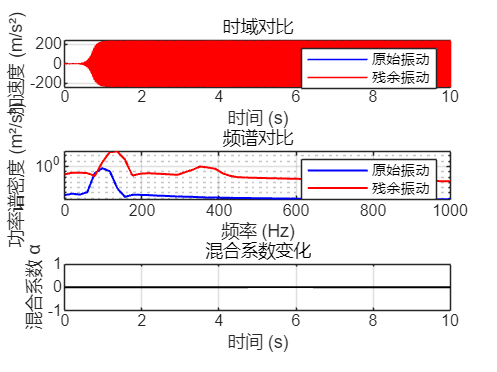


% 绘制结果（时域、频域、混合系数等）
figure;
subplot(3,1,1);
plot(t, vibration_raw, 'b', 'LineWidth', 0.5);
hold on;
plot(t, error_signal, 'r', 'LineWidth', 0.5);
xlabel('时间 (s)'); ylabel('加速度 (m/s²)');
legend('原始振动', '残余振动');
title('时域对比');
grid on;

subplot(3,1,2);
semilogy(f, Pv, 'b', 'LineWidth', 1);
hold on;
semilogy(f, Pe, 'r', 'LineWidth', 1);
xlabel('频率 (Hz)'); ylabel('功率谱密度 (m²/s³)');
legend('原始振动', '残余振动');
title('频谱对比');
xlim([0, 1000]);
grid on;

subplot(3,1,3);
plot(t, alpha_history, 'k', 'LineWidth', 1);
xlabel('时间 (s)'); ylabel('混合系数 α');
title('混合系数变化');
grid on;

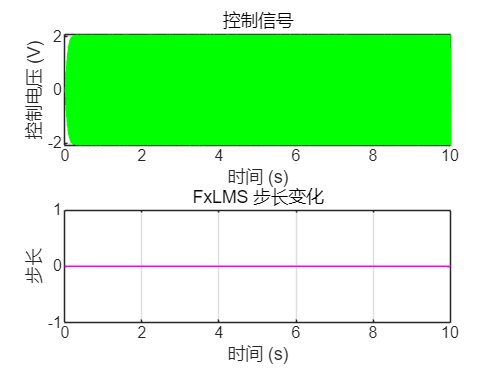


figure;
subplot(2,1,1);
plot(t, control_signal, 'g', 'LineWidth', 0.5);
xlabel('时间 (s)'); ylabel('控制电压 (V)');
title('控制信号');
grid on;

subplot(2,1,2);
plot(t, mu_history, 'm', 'LineWidth', 0.5);
xlabel('时间 (s)'); ylabel('步长');
title('FxLMS 步长变化');
grid on;

## 8. 保存结果

save('simulation_results.mat', 't', 'vibration_raw', 'error_signal', ...
    'control_signal', 'alpha_history', 'mu_history', 'rms_history', ...
    'rms_error', 'peak_error', 'convergence_time', 'total_reduction');

fprintf('\n结果已保存至 simulation_results.mat\n');


结果已保存至 simulation_results.mat



% 保存训练数据
if alpha_max == 0
    save('training_data.mat', 'data_collect');
    fprintf('训练数据已保存至 training_data.mat，共 %d 个样本\n', size(data_collect.features,1));
end

训练数据已保存至 training_data.mat，共 9999 个样本
